## Analitic Jacobian

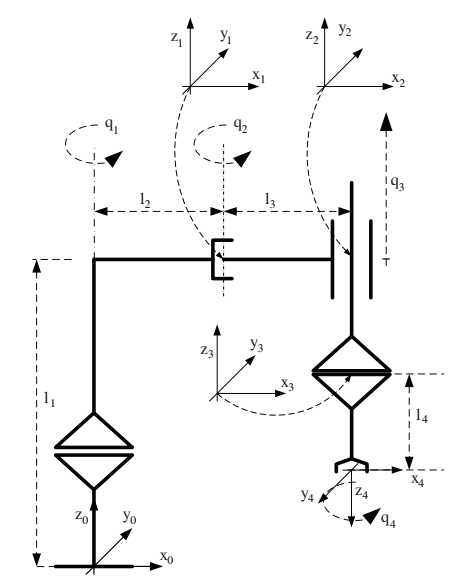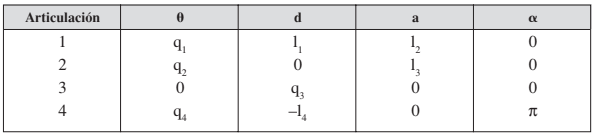

% Solving for [x_dot y_dot z_dot phi_dot theta_dot psi_dot]'
% Relates articular velocities (q1,...qn) with location velocities (x_dot, y_dot,...psi_dot)
syms q1 q2 q3 q4 l1 l2 l3 l4

R = [cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1];
T1 = HTM(R);
p1 = [0; 0; l1];
T2 = HTM(eye(3), p1);
p2 = [l2; 0; 0];
T3 = HTM(eye(3), p2);

A01 = T1 * T2 * T3

$$A01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & l_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & l_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R = [cos(q2) -sin(q2) 0; sin(q2) cos(q2) 0; 0 0 1];
T1 = HTM(R);
p = [l3; 0; 0];
T2 = HTM(eye(3), p);

A12 = T1 * T2

$$A12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & l_{3}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{3}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = [0; 0; q3];
T1 = HTM(eye(3), p);

A23 = T1

$$A23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R1 = [cos(q4) -sin(q4) 0; sin(q4) cos(q4) 0; 0 0 1];
T1 = HTM(R1);
p = [0; 0; -l4];
T2 = HTM(eye(3), p);
R2 = rotx(180);     % pi
T3 = HTM(R2);

A34 = T1 * T2 * T3

$$A34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & \sin\left(q_{4}\right) & 0 & 0\\ \sin\left(q_{4}\right) & -\cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & -1 & -l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A04 = simplify(A01 * A12 * A23 * A34)

$$A04 = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}+q_{4}\right) & \sin\left(q_{1}+q_{2}+q_{4}\right) & 0 & l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}+q_{4}\right) & -\cos\left(q_{1}+q_{2}+q_{4}\right) & 0 & l_{3}\,\sin\left(q_{1}+q_{2}\right)+l_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & -1 & l_{1}-l_{4}+q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Direct kinematics
x = A04(1,4)

$$x = l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right)$$

y = A04(2,4)

$$y = l_{3}\,\sin\left(q_{1}+q_{2}\right)+l_{2}\,\sin\left(q_{1}\right)$$

z = A04(3,4)

$$z = l_{1}-l_{4}+q_{3}$$

phi = q1 + q2 + q4;
theta = 180;         % pi
psi = 180;           % pi

% Euler angles WVW
R1 = [cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1];
R2 = roty(theta);
R3 = rotz(psi);

all(all(  R1 * R2 * R3 == A04(1:3,1:3)  ))

ans = logical
   1


% EXAMPLE 1
ART_pos = [q1 q2 q3 q4];
FA_pos = [x y z phi theta psi];

% Completing Analitic Jacobian Ja
Ja = jacobian(FA_pos, ART_pos)

$$Ja = \left(\begin{array}{cccc} -l_{3}\,\sin\left(q_{1}+q_{2}\right)-l_{2}\,\sin\left(q_{1}\right) & -l_{3}\,\sin\left(q_{1}+q_{2}\right) & 0 & 0\\ l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right) & l_{3}\,\cos\left(q_{1}+q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 1 & 1 & 0 & 1\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% Example 1 data
ART_pos = [pi/6 pi/4 0.75 0];       % [rad rad m rad]
ART_vel = [pi/2; pi/2; 1; pi/4];      % [rad/s rad/s m/s rad/s]
Ja = vpa(subs(Ja, [q1 q2 q3 q4 l2 l3], [ART_pos 1 1]), 3)

$$Ja = \left(\begin{array}{cccc} -1.47 & -0.966 & 0 & 0\\ 1.12 & 0.259 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 1.0 & 1.0 & 0 & 1.0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% Final actuator's location velocities
FA_vels = vpa(Ja * ART_vel, 3)

$$FA\_vels = \left(\begin{array}{c} -3.82\\ 2.17\\ 1.0\\ 3.93\\ 0\\ 0 \end{array}\right)$$

x_dot = FA_vels(1)

$$x\_dot = -3.819943643175065517425537109375$$

y_dot = FA_vels(2)

$$y\_dot = 2.1734535338473506271839141845703$$

z_dot = FA_vels(3)

$$z\_dot = 1.0$$

phi_dot = FA_vels(4)

$$phi\_dot = 3.9269908169517293572425842285156$$

theta_dot = FA_vels(5)

$$theta\_dot = 0$$

psi_dot = FA_vels(6)

$$psi\_dot = 0$$

% EXAMPLE 2
ART_pos = [q1 q2 q3 q4];
FA_pos = [x y z phi theta psi];

%Completing Analitic Jacobian Ja
Ja = jacobian(FA_pos, ART_pos);
% Example 2 data
ART_pos = [pi/3 pi/2 0.75 0];       % [rad rad m rad]
Ja = vpa(subs(Ja, [q1 q2 q3 q4 l2 l3], [ART_pos 1 1]), 3)

$$Ja = \left(\begin{array}{cccc} -1.37 & -0.5 & 0 & 0\\ -0.366 & -0.866 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 1.0 & 1.0 & 0 & 1.0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% Final actuator's location velocities
FA_vels = vpa(Ja * ART_vel, 3)

$$FA\_vels = \left(\begin{array}{c} -2.93\\ -1.94\\ 1.0\\ 3.93\\ 0\\ 0 \end{array}\right)$$

x_dot = FA_vels(1)

$$x\_dot = -2.9311458499869331717491149902344$$

y_dot = FA_vels(2)

$$y\_dot = -1.9353008829348254948854446411133$$

z_dot = FA_vels(3)

$$z\_dot = 1.0$$

phi_dot = FA_vels(4)

$$phi\_dot = 3.9269908169517293572425842285156$$

theta_dot = FA_vels(5)

$$theta\_dot = 0$$

psi_dot = FA_vels(6)

$$psi\_dot = 0$$

## Geometric Jacobian

% Solving for [vx vy vz wx wy wz]'
% Relates articular velocities (q1,...qn) with linear and angular velocities (vx, vy,...wz)
syms q1_dot q2_dot q3_dot q4_dot

px = A04(1,4)

$$px = l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right)$$

py = A04(2,4)

$$py = l_{3}\,\sin\left(q_{1}+q_{2}\right)+l_{2}\,\sin\left(q_{1}\right)$$

pz = A04(3,4)

$$pz = l_{1}-l_{4}+q_{3}$$

p = [px py pz];
ART_pos = [q1 q2 q3 q4];

% Calculating Jv
Jv = jacobian(p, ART_pos)

$$Jv = \left(\begin{array}{cccc} -l_{3}\,\sin\left(q_{1}+q_{2}\right)-l_{2}\,\sin\left(q_{1}\right) & -l_{3}\,\sin\left(q_{1}+q_{2}\right) & 0 & 0\\ l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right) & l_{3}\,\cos\left(q_{1}+q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

R = A04(1:3,1:3)'

$$R = \left(\begin{array}{ccc} \cos\left(\bar{q_{1}}+\bar{q_{2}}+\bar{q_{4}}\right) & \sin\left(\bar{q_{1}}+\bar{q_{2}}+\bar{q_{4}}\right) & 0\\ \sin\left(\bar{q_{1}}+\bar{q_{2}}+\bar{q_{4}}\right) & -\cos\left(\bar{q_{1}}+\bar{q_{2}}+\bar{q_{4}}\right) & 0\\ 0 & 0 & -1 \end{array}\right)$$

% Taking derivative with respect to q1, q2 or q4 will result in the same result
R_dot = diff(R, q1) * (q1_dot + q2_dot + q4_dot)

$$R\_dot = \left(\begin{array}{ccc} -\sin\left(\bar{q_{1}}+\bar{q_{2}}+\bar{q_{4}}\right)\,\left(q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}\right) & \cos\left(\bar{q_{1}}+\bar{q_{2}}+\bar{q_{4}}\right)\,\left(q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}\right) & 0\\ \cos\left(\bar{q_{1}}+\bar{q_{2}}+\bar{q_{4}}\right)\,\left(q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}\right) & \sin\left(\bar{q_{1}}+\bar{q_{2}}+\bar{q_{4}}\right)\,\left(q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}\right) & 0\\ 0 & 0 & 0 \end{array}\right)$$

Omega = simplify(R_dot * R)

$$Omega = \left(\begin{array}{ccc} 0 & -q_{\dot{1}}-q_{\dot{2}}-q_{\dot{4}} & 0\\ q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}} & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

wx = Omega(3,2)

$$wx = 0$$

wy = Omega(1,3)

$$wy = 0$$

wz = Omega(2,1)

$$wz = q_{\dot{1}}+q_{\dot{2}}+q_{\dot{4}}$$

w = [wx wy wz];
ART_vel = [q1_dot q2_dot q3_dot q4_dot];

% Calculating Jw
Jw = jacobian(w, ART_vel)

$$Jw = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 0 & 1 \end{array}\right)$$

% Completing Geometric Jacobian J
J = [Jv; Jw]

$$J = \left(\begin{array}{cccc} -l_{3}\,\sin\left(q_{1}+q_{2}\right)-l_{2}\,\sin\left(q_{1}\right) & -l_{3}\,\sin\left(q_{1}+q_{2}\right) & 0 & 0\\ l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right) & l_{3}\,\cos\left(q_{1}+q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 0 & 1 \end{array}\right)$$

% Using data from example in geometric jacobian
ART_pos = [pi/3 pi/2 0.75 0];       % [rad rad m rad]
ART_vel = [pi/2; pi/2; 1; pi/4];      % [rad/s rad/s m/s rad/s]
J = vpa(subs(J, [q1 q2 q3 q4 l2 l3], [ART_pos 1 1]), 3)

$$J = \left(\begin{array}{cccc} -1.37 & -0.5 & 0 & 0\\ -0.366 & -0.866 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1.0 & 1.0 & 0 & 1.0 \end{array}\right)$$

% Calculating Linear and Angular Velocities
LA_vel = vpa(J * ART_vel, 3)

$$LA\_vel = \left(\begin{array}{c} -2.93\\ -1.94\\ 1.0\\ 0\\ 0\\ 3.93 \end{array}\right)$$

##  Relationship Between Analitic and Geometric Jacobian

I = eye(3);
O = zeros(3,3);
Q = [0 -sin(phi) cos(phi)*sin(theta); 0 cos(phi) sin(phi)*sin(theta); 1 0 cos(theta)];

% Analitic to Geometric Jacobian
Ja_J = vpa([I O; O Q] * Ja, 3)

$$Ja\_J = \left(\begin{array}{cccc} -1.37 & -0.5 & 0 & 0\\ -0.366 & -0.866 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1.0 & 1.0 & 0 & 1.0 \end{array}\right)$$

% Geometric to Analitic Jacobian
J_Ja = vpa([I O; O Q^(-1)] * J, 3)

$$J\_Ja = \left(\begin{array}{cccc} -1.37 & -0.5 & 0 & 0\\ -0.366 & -0.866 & 0 & 0\\ 0 & 0 & 1.0 & 0\\ 1.0 & 1.0 & 0 & 1.0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

## Singularity Configuration

% Using Jv from previous example while sparing q4 degree of freedom
Jdet = simplify(det(Jv(:,1:3)))

$$Jdet = l_{2}\,l_{3}\,\sin\left(q_{2}\right)$$

% Jdet will be zero if q2 is 0 or pi
% q2 = 0 or pi are the singular configuration of the robot

## Example Visualization

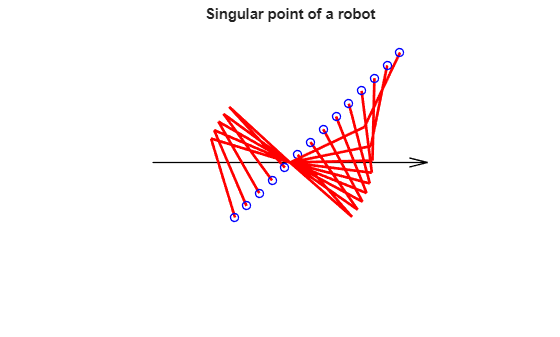

% Same example while sparing q4 and q3 degrees of freedom (Until HTM A02 instead of A04)
syms q1 q2 v_x v_y

% Data
d2 = 3;                     % cm
d3 = 3;                     % cm
vx = 0.6;                   % cm/s
vy = 0.8;                   % cm/s
t = linspace(0,10,130);     % 10 seconds

% Homogeneous Transformation Matrix
A02 = simplify(A01 * A12);

% Solving for Jacobian (Space work reduced to work with a square Jacobian)
px = A02(1,4);
py = A02(2,4);
pz = A02(3,4);
p = [px py];
ART_pos = [q1 q2];
Jv = jacobian(p, ART_pos);

% Degree of freedom q2 data
q2_pos = [];
q2_vels = [];

% End Effector's Trayectory
trayectory_x = linspace(-2, 4, 130);
trayectory_y = linspace(-2, 4, 130);

% Ploting 2D space
figure;
hold on;
quiver(-5, 0, 10, 0, 0, 'k', 'LineWidth',1);
title('Singular point of a robot');
grid on; axis equal; axis off;
xticks(-5:5); yticks(-5:5); xlim([-5 5]); ylim([-5 5]);

% Finding every q1 and q2 angles for each point in the end effector's trayectory
for p = 1:length(trayectory_x)
    
    % End Effector's Position
    x = trayectory_x(p);
    y = trayectory_y(p);

    % Inverse Kinematics (Geometric Method)
    r = (x^2 + y^2 - d2^2 - d3^2)/(2*d2*d3);
    
    theta2 = acos(r);
    beta = atan2(y, x);
    alpha = atan2(d3*sin(theta2), (d2 + d3*cos(theta2)));
    theta1 = beta - alpha;
    
    % Solving for q2 angular velocity
    J = vpa(subs(Jv, [q1 q2 l2 l3], [theta1 theta2 d2 d3]), 3);
    ART_vel = J^(-1) * [vx; vy];

    % Storing data
    q2_pos = [q2_pos theta2];
    q2_vels = [q2_vels ART_vel(2)];
    
    if mod(p, 10) == 0 || x == trayectory_x(1) && y == trayectory_y(1)
        % Limb's positions
        x1 = d2 * cos(theta1);
        y1 = d2 * sin(theta1);
        x2 = x1 + d3 * cos(theta1 + theta2);
        y2 = y1 + d3 * sin(theta1 + theta2);
        
        % Ploting limbs (Red lines) and positions
        plot([0 x1], [0 y1], 'r', 'LineWidth', 2);
        plot([x1 x2], [y1 y2], 'r', 'LineWidth', 2);
        plot(x, y, 'bo', 'LineWidth', 1);
    end
end
hold off;

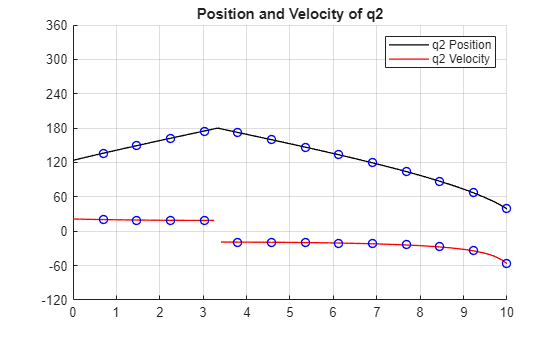

% Converting radians into degrees
q2_pos = rad2deg(q2_pos);
q2_vels = rad2deg(q2_vels);

% Ploting q2 positions and velocities
figure;
hold on;
plot(t, q2_pos, 'k', 'LineWidth',1);
plot(t, q2_vels, 'r', 'LineWidth',1);
for p = 1:length(q2_pos)
    if mod(p, 10) == 0 || x == trayectory_x(1) && y == trayectory_y(1)
        plot(t(p), q2_pos(p), 'bo', 'LineWidth', 1);
        plot(t(p), q2_vels(p), 'bo', 'LineWidth', 1);
    end
end
title('Position and Velocity of q2');
grid on; legend('q2 Position', 'q2 Velocity');
xticks(0:10); yticks(-120:60:360); xlim([0 10]); ylim([-120 360]);
hold off;